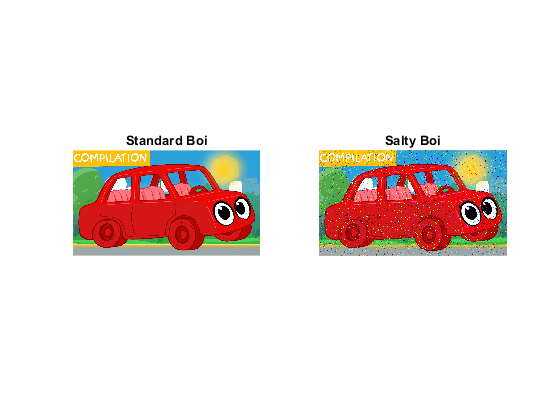

basicCar = imread('redcar', "jpg");
noisyCar = imnoise(basicCar, 'salt & pepper');
figure
subplot(1,2,1);
imshow(basicCar);
title("Standard Boi");
subplot(1,2,2);
imshow(noisyCar);
title("Salty Boi");

Guassian vs salt+pepper Noise

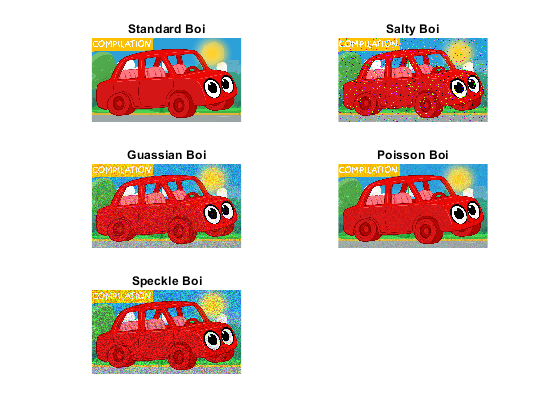

GuassianBoi = imnoise(basicCar,"gaussian");
Poisson = imnoise(basicCar, 'poisson');
SpeccleBoi = imnoise(basicCar, 'speckle');

figure
subplot(3,2,1);
imshow(basicCar);
title("Standard Boi");
subplot(3,2,2);
imshow(noisyCar);
title("Salty Boi");
subplot(3,2,3);
imshow(GuassianBoi);
title("Guassian Boi");
subplot(3,2,4);
imshow(Poisson);
title("Poisson Boi");
subplot(3,2,5);
imshow(SpeccleBoi);
title("Speckle Boi");

Mean Filter

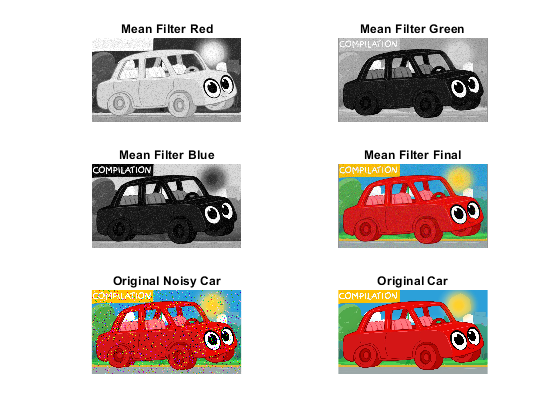

h = 1/16*ones(4);

imfiltRed = conv2(h,noisyCar(:,:,1));
imfiltGreen = conv2(h,noisyCar(:,:,2));
imfiltBlue = conv2(h,noisyCar(:,:,3));
imfiltBlue = uint8(imfiltBlue);
imfiltGreen = uint8(imfiltGreen);
imfiltRed = uint8(imfiltRed);

figure
subplot(3,2,1);
imshow(imfiltRed);
title("Mean Filter Red")
subplot(3,2,2);
imshow(imfiltGreen);
title("Mean Filter Green")
subplot(3,2,3);
imshow(imfiltBlue);
title("Mean Filter Blue")
outputCar = cat(3,imfiltRed, imfiltGreen, imfiltBlue);

subplot(3,2,4);
imshow(outputCar);
title("Mean Filter Final")
subplot(3,2,5);
imshow(noisyCar);
title("Original Noisy Car");
subplot(3,2,6);
imshow(basicCar);
title("Original Car");

Median Filter

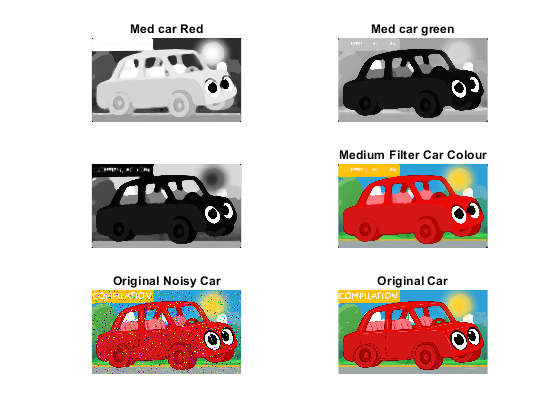

MedCarRed = medfilt2(noisyCar(:,:,1),[32,32]);
MedCarGreen = medfilt2(noisyCar(:,:,2),[32,32]);
MedCarBlue = medfilt2(noisyCar(:,:,3),[32,32]);
figure
subplot(3,2,1);
imshow(MedCarRed);
title("Med car Red");
subplot(3,2,2);
imshow(MedCarGreen);
title("Med car green");
subplot(3,2,3);
imshow(MedCarBlue);
medCarColour = cat(3,MedCarRed, MedCarGreen, MedCarBlue);
subplot(3,2,4);
imshow(medCarColour);
title("Medium Filter Car Colour");
subplot(3,2,5);
imshow(noisyCar);
title("Original Noisy Car");
subplot(3,2,6);
imshow(basicCar);
title("Original Car");

Advanced: Conv function

%%% Padding by default set to no padding, 1 = no padding, 2 = same padding

function convImage = conv(originalImage, ConvMat,padding)
    [ConvHeight,ConvWidth] = size(ConvMat);
    xOffset = 0;
    yOffset = 0;
    if(nargin < 2)
        padding = 1;
    end
    if(padding == 1)
        %Calculate padding offset
        % 1 1 1 
        % 1 x 1
        % 1 1 1
        xOffset = ConvWidth;
        yOffset = ConvHeight;
    end
    ChannelOne = originalImage(:,:,1);
    ChannelTwo = originalImage(:,:,2);
    ChannelThree = originalImage(:,:,3);
    [imgHeight, imgWidth] = size(ChannelOne);
    for y = yOffset:imgWidth
        for x = xOffset:imgHeight
            targetCell = ChannelOne(x, y);
            
        end
    end
    convImage = cat(3,ChannelOne, ChannelTwo, ChannelThree);
end


%convImage(noisyCar,h);

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.